# Input file

filename = 'OTB';
load(append(filename, '.mat'))
% M= readmatrix(append(filename,'.mat')); %read in csv file
M = [Time Data]

M = 65712×65 single 矩阵
         0    0.1724    0.1724    0.1729    0.1856    0.1806    0.1785    0.1846    0.1816    0.1836    0.1877    0.1862    0.1872    0.1872    0.1912    0.1851    0.1902    0.1851    0.1928    0.1887    0.1897    0.1892    0.1968    0.1907    0.1933    0.1887    0.1907    0.1897    0.1923    0.1872    0.1912    0.1872    0.1897    0.1877    0.1953    0.1928    0.1862    0.1958    0.1902    0.1831    0.1918    0.1973    0.1958    0.1963    0.1973    0.1902    0.1953    0.1918    0.1882    0.1877
    0.0005    0.1139    0.1088    0.1104    0.1246    0.1195    0.1195    0.1211    0.1165    0.1185    0.1221    0.1251    0.1241    0.1211    0.1297    0.1231    0.1277    0.1231    0.1272    0.1246    0.1297    0.1261    0.1348    0.1256    0.1317    0.1333    0.1373    0.1282    0.1287    0.1256    0.1282    0.1231    0.1236    0.1302    0.1312    0.1328    0.1246    0.1333    0.1261    0.1231    0.1307    0.1358    0.1343    0.1358    0.1338    0.1312    0.1348    0.

%extract data from file, adjust use first section if no time column, second if csv contains time column.
%Change channel_select within section that is used

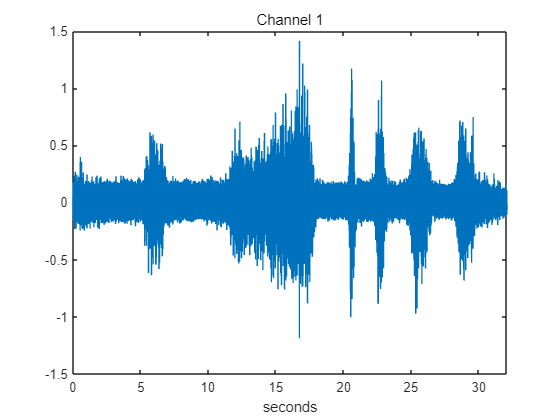

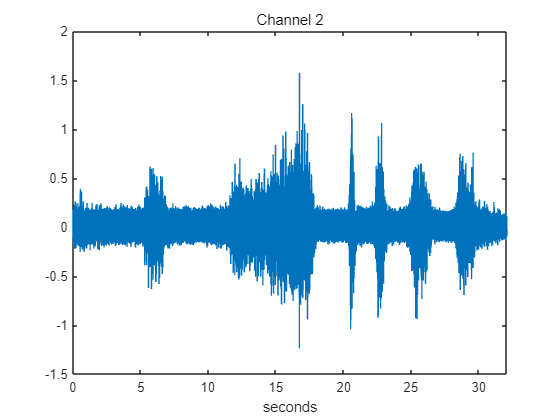

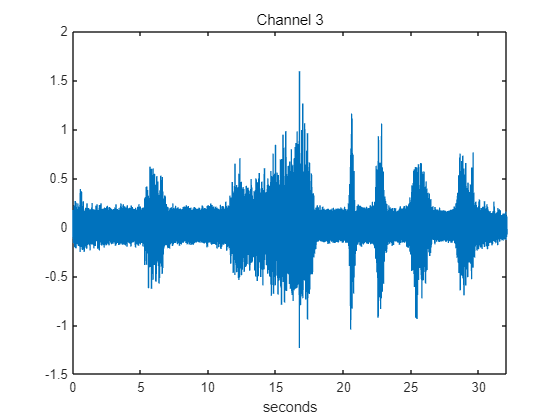

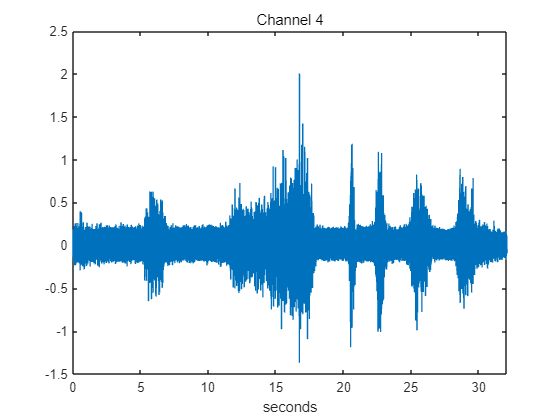

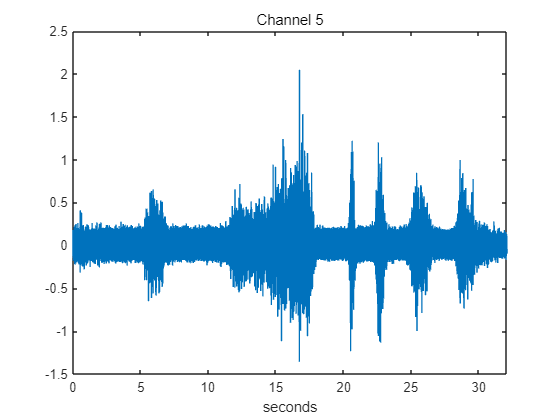

%for files with time data
time= M(:,1); % first column is the time series
fs= (time(2)-time(1))^-1; % calculate the sample frequecy
channel_number= size(M,2)-1; % num of channels in the database
channel_select= 5;% select channel for testing, make sure channel_select<= channel_number
test_input= M(:,channel_select + 1);%select desired channel, add 1 since first col is time, make sure channel_select<= channel_number
total_samples = size(time,1);%get total number of samples
%plot channel data
for i=1:channel_select
    figure('Color',[1 1 1]);plot(time,M(:,i+1)); %plot each channel
    str= sprintf('Channel %d',i);
    xlabel('seconds');title(str);xlim([time(1) time(size(time,1))]); % label and title each plots
end

## Filter Signal

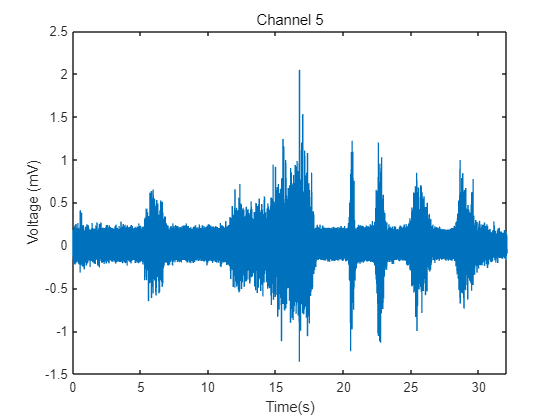

%close other channels and plot selected channel
close all
figure('Color',[1 1 1]);plot(time,test_input);
str= sprintf('Channel %d',channel_select);
xlabel('Time(s)');title(str);xlim([time(1) time(size(time,1))]); % label and title each plots
ylabel('Voltage (mV)')

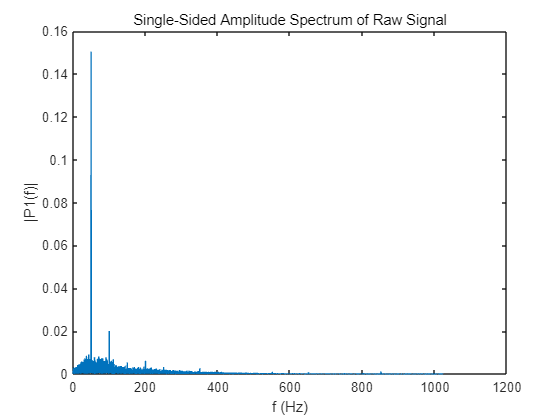

%plot fft of signal
L = size(test_input,1);
F = fft(test_input);
f = fs*(0:(L/2))/L;
P2 = abs(F/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
figure;plot(f,P1)
amp_spectrum_raw = 'Single-Sided Amplitude Spectrum of Raw Signal';
title((amp_spectrum_raw));
xlabel('f (Hz)');
ylabel('|P1(f)|');

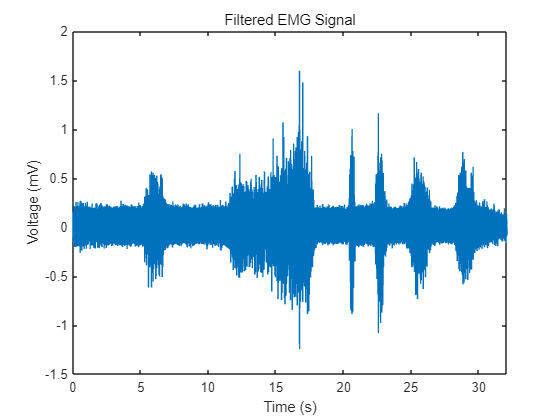


%bandpass signal based on fft
in = test_input;
low = 50;
high = 500;
[in,d] = bandpass(in,[low high],fs);


%plot filtered signal
freq_range = sprintf(' %d to %d',low,high);
figure('Color',[1 1 1]);plot(time,in);xlim([time(1) time(size(time,1))]) %plot each channel
str= sprintf('Filtered EMG Signal');
xlabel('Time (s)');title(str); % label and title each plots
ylabel('Voltage (mV)')

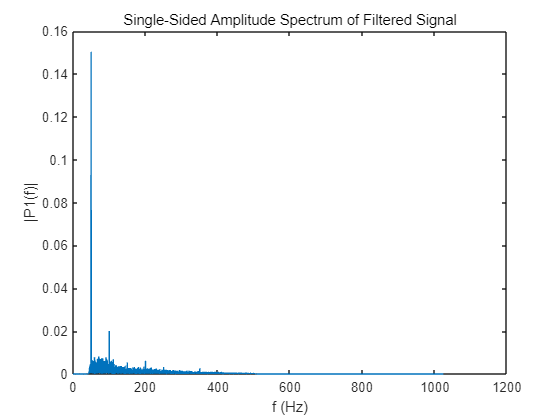


%plot fft of filtered signal to check filtering, not used in report
figure;
L = size(in,1);
F = fft(in);
f = fs*(0:(L/2))/L;
P2 = abs(F/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
plot(f,P1)
amp_spectrum = 'Single-Sided Amplitude Spectrum of Filtered Signal';
title((amp_spectrum))
xlabel('f (Hz)')
ylabel('|P1(f)|')

## Detect Spikes

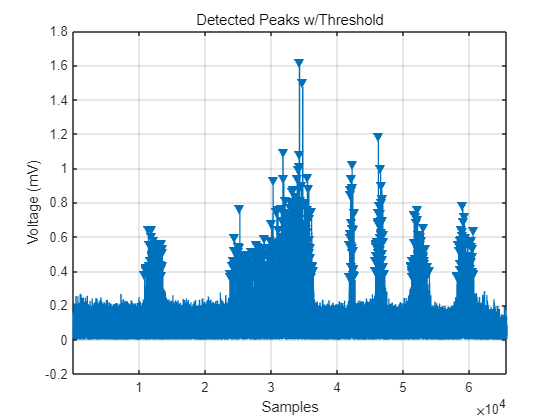

%parameters

using_neo =0; %using non-linear energy operator doesn't improve performance currently
use_min_dist = 1; %should use to avoid alignment issues
num_samples = 16;%determine now since will be used to find minimum distance for peak detection to avoid multiple spikes in same window

%run stage

if(use_min_dist)
    min_dist_samp = num_samples;%set minimum distance between spikes for detection
else
    min_dist_samp = 0 ;
end

if(using_neo==0)%if not using neo
    emg_rms = rms(in);
    threshold = 2*emg_rms;%increase if detecting too many false spikes
    figure;
    %plot peaks detected
    findpeaks(abs(in),'MinPeakHeight',threshold,'MinPeakDistance',min_dist_samp);%display
    title('Detected Peaks w/Threshold')
    ylabel('Voltage (mV)')
    xlabel('Samples')
    %store peaks and peak locations
    [pks_abs,locs_abs] = findpeaks(abs(in),'MinPeakHeight',threshold,'MinPeakDistance',min_dist_samp);
    locs = locs_abs;
    pks = pks_abs;
    
else
    neo = in(2:end-1).^2 - in(1:end-2).*in(3:end);
    neo_threshold = 3*rms(neo);
    figure;
    %plot peaks detected
    findpeaks(neo,'MinPeakHeight',neo_threshold,'MinPeakDistance',min_dist_samp)%display peaks
    title('Detected Peaks w/NEO threshold');
    xlabel('Voltage (mV');
    ylabel('Time (s)');
    %store peaks and peak locations
    [pks_neo,locs_neo] = findpeaks(neo,'MinPeakHeight',neo_threshold);
    locs = locs_neo;
    pks = pks_neo;
end

## Align Spikes

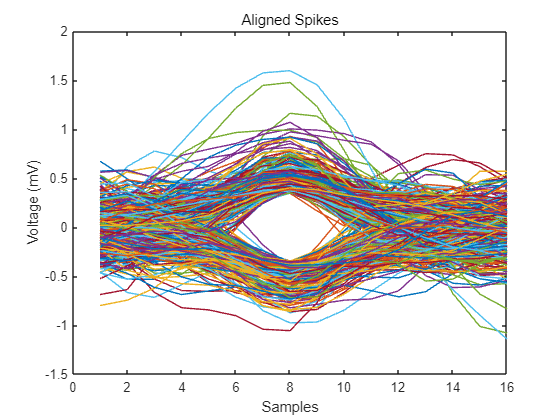

%parameters

samp_bef = floor((num_samples-1)/2);%num samples to include after spike
samp_after = ceil((num_samples-1)/2);%num samples to include after spike

%run stage

pks = pks((locs>samp_bef)&((locs+samp_after)<total_samples)); %only keep spikes which can be fully sampled
locs = locs((locs>samp_bef)&((locs+samp_after)<total_samples));%only keep spikes which can be fully sampled

center_sample = samp_bef+1;%get sample location of spike center
num_spikes = size(locs,1);%get total number of spikes
spike_arr = in(locs(1)-samp_bef:locs(1)+samp_after);%load first spike waveform into array
%load rest of the spikes
for i=2:num_spikes
    spike = in(locs(i)-samp_bef:locs(i)+samp_after);
    spike_arr = cat(2,spike,spike_arr);
end
spike_arr = spike_arr'; %transpose to get array of dimension (num_spikes*num_samples) where rows are observations and columns are features

%graph spikes
samp_nums = 1:num_samples;
figure;
for i=1:num_spikes
    plot(samp_nums,spike_arr(i,:))
    hold on
    xlabel('Samples')
    ylabel('Voltage (mV)')
    title('Aligned Spikes')
end
hold off %no longer add plots to current figure

## Extract Features

[coeff,score,latent,tsquared,explained,means] = pca(spike_arr); %run pca to find important features

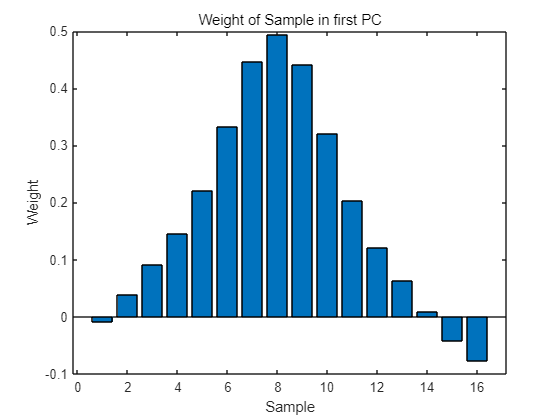


%plot contribution of each sample to first PC
figure;
bar(coeff(:,1))
xlabel('Sample')
ylabel('Weight')
title('Weight of Sample in first PC')

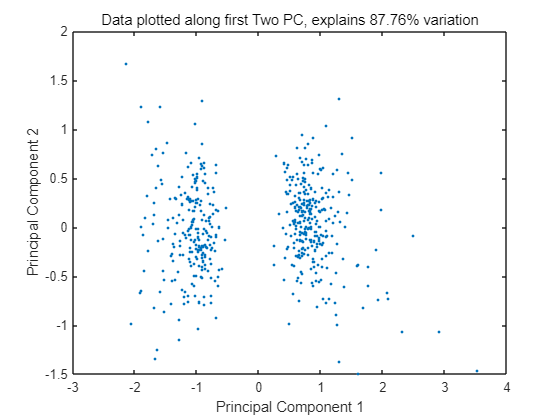


%plot data along first two PCS, use to determine initial number of clusters for k-means
figure;
plot(score(:,1),score(:,2),'.')
explained_2PCs = explained(1)+explained(2);%get variance explained by first two PCs
pca_title = sprintf('Data plotted along first Two PC, explains %.2f%% variation',explained_2PCs);%display explained variation
title(pca_title);
xlabel('Principal Component 1');
ylabel('Principal Component 2');

## Cluster Spikes

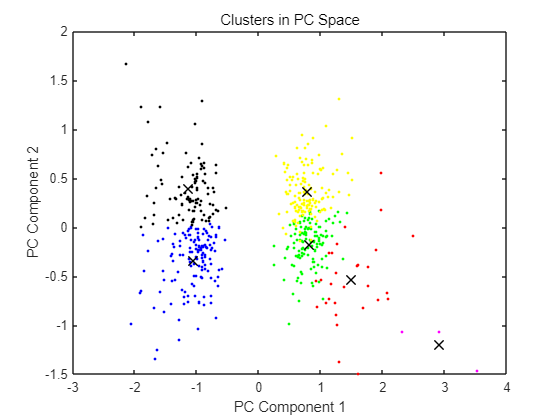

%params
using_pcascores = 0;%set to 1 to run k-means using reduced version of data
num_comp = 5;%number of dimensions to reduce to (if using pca scores for k-means)

rng(2)%can change if k-means result is not accurate
num_clusters = 6;

%run stage

if(using_pcascores)
    [idx,C] = kmeans(score(:,1:num_comp),num_clusters); %input data in PC space to k-means, performance is generally not improved
    
else
    [idx,C] = kmeans(spike_arr,num_clusters);%input data in original space to k-means
end



color = {'r';'g';'b';'y';'m';'k'};%color up to 6 clusters, add color if using more
if(using_pcascores==0)
    pca_C = (C-means)*coeff;%shift k-means centroids to PC space if not inputting from PC space
else
    pca_C = C; %centroid already in PC space
end

%plot spikes in PC space, color according to cluster
figure;
for i=1:num_clusters
    plot(score(idx==i,1),score(idx==i,2),'.','color',color{i})
    hold on
    plot(pca_C(i,1),pca_C(i,2),'x','color','black','MarkerSize',10,'LineWidth',1)%plot centroid as black X
    title('Clusters in PC Space')
    xlabel('PC Component 1')
    ylabel('PC Component 2')
end

hold off

## Classify

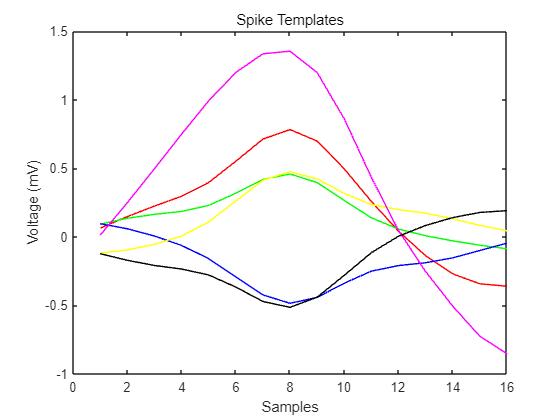

if(using_pcascores)
    C = C*coeff(:,1:num_comp)'+means;%convert centroid back to original space if pca space was used in k-means input
end
%plot spike template for each cluster
figure;
for i=1:num_clusters
    plot(samp_nums,C(i,:),'color',color{i})
    hold on
    xlabel('Samples')
    ylabel('Voltage (mV)')
    title('Spike Templates')
end

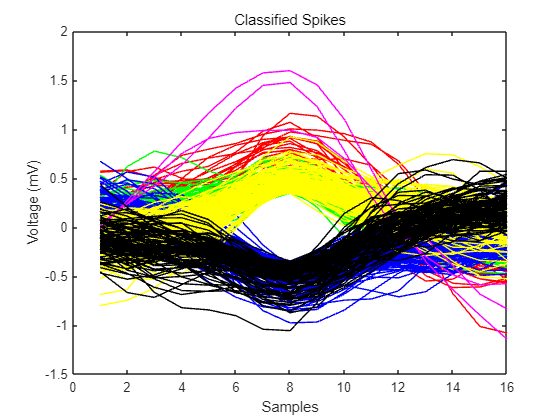


%plot all spikes classified
figure;
for i=1:num_clusters
    plot(samp_nums,spike_arr(idx==i,:),'color',color{i})%plot spikes colored by cluster
    hold on
    xlabel('Samples')
    ylabel('Voltage (mV)')
    title('Classified Spikes')
end

## Analysis

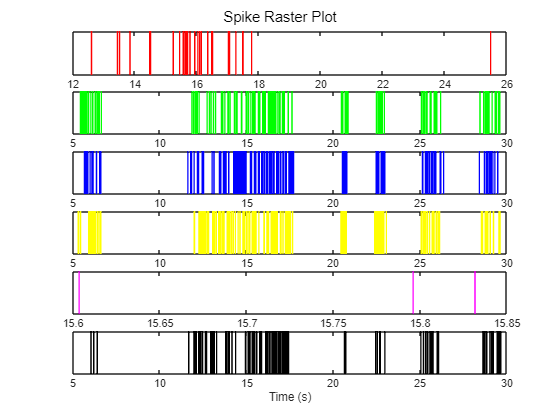

%raster plot, each line represents a spike at that particular time
figure;
for i=1:num_clusters
    subplot(num_clusters,1,i);
    num_in_class = size(locs(idx==i),1);
    plot([locs(idx==i),locs(idx==i)]/fs,[0 1],'-','color',color{i})
    set(gca,'Ytick',[])
    set(gca,'YTickLabel',[]);
    xlabel('Time (s)')
    sgtitle('Spike Raster Plot','FontSize',11)
end

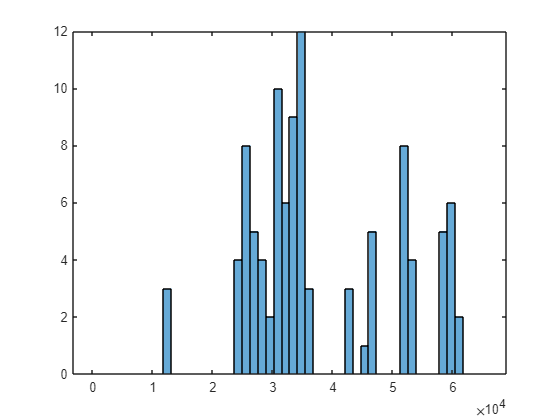


%get firing rates
bin_size = total_samples/50; %in samples
edges = 0:bin_size:total_samples;%create 100 bins to cover whole range
binned_spikes = zeros(3,size(edges,2)-1);%initialize array

figure;
for i=1:num_clusters
    h = histogram(locs(idx==i),edges);%count number of spikes in each bin, does not plot
    binned_spikes(i,:) = h.Values;%get values from histogram object
end

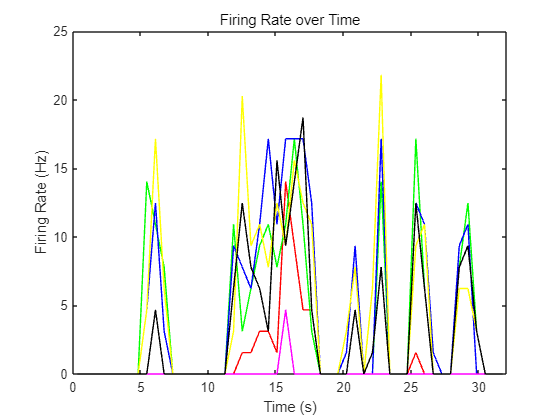

firing_rates = (binned_spikes/bin_size)*fs;

%plot firing rates
bin_centers = (edges(1,2:end)+edges(1,1:end-1))/2;%get bin center (approx. where firing rate is calculated)
for i=1:num_clusters
    plot(bin_centers/fs,firing_rates(i,:),'color',color{i})
    xlim([time(1) time(size(time,1))])
    hold on
    title('Firing Rate over Time')
    xlabel('Time (s)')
    ylabel('Firing Rate (Hz)')
end

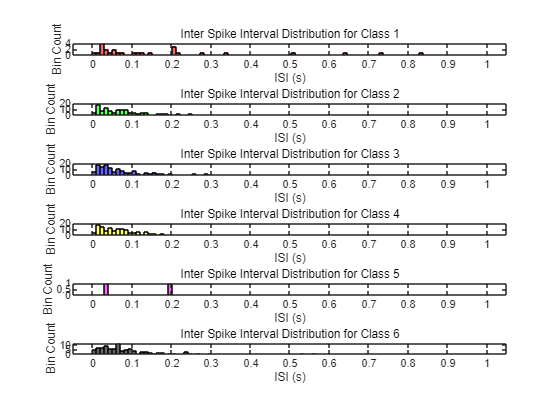


%calculate, plot, and store ISIs
isi_cell = {};
figure;
for i=1:num_clusters
    subplot(num_clusters,1,i)
    isi = diff(locs(idx==i))/fs;
    isi_cell{i} = isi;
    edges = linspace(0,1,100); %100 edges, relevant ISIs are between 0 to 1s since freq of spikes is from 1-20Hz
    histogram(isi,edges,'FaceColor',color{i})
    isi_title = sprintf('Inter Spike Interval Distribution for Class %d',i);
    title(isi_title);
    xlabel('ISI (s)');
    ylabel('Bin Count');
end